# NUMERICAL VALIDATION OF ROBUST POSITIONING CONTROLLER FOR MACHINE  TOOLS APPLICATION

## Transfer Function

  
$$G_m(s) = \frac{Y(s)}{U(s)} = \frac{A}{s^2 + Bs + C}e^{-s\cdot T_d}$$


Clear; close all; clc;

## SISO tool

% Constants of Transfer Function
A = 78020;
B = 163;
C = 193.3;
Td = 0.0012;

% SISO tool initialization
% s = tf('s')
% sisotool((A/s^2+B*s+C)*exp(-s*Td), 1)

% Define a transfer function with time delay
numerator = A;             % A
denominator = [1, B, C];      % 1, B, C respectively
time_delay = Td;               % Time delay in seconds

% Create the transfer function with time delay
input = 'R(s)';
output = 'Y(s)';
sys = tf(numerator, denominator, 'InputName', input, ...
                                 'OutputName', output, 'InputDelay', time_delay)

sys =
 
  From input "R(s)" to output "Y(s)":
                          78020
  exp(-0.0012*s) * -------------------
                   s^2 + 163 s + 193.3
 
Continuous-time transfer function.




% Display the transfer function with time delay
disp('Transfer Function:');

Transfer Function:


disp(sys);

  tf with properties:

       Numerator: {[0 0 78020]}
     Denominator: {[1 163 193.3000]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0.0012
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {'R(s)'}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {'Y(s)'}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



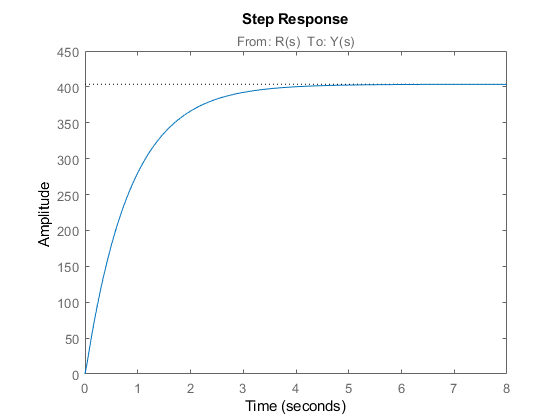


% Plot step response
step(sys);

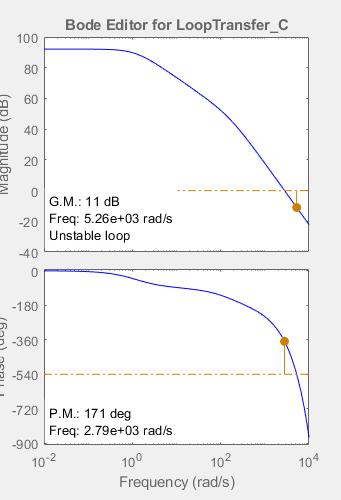

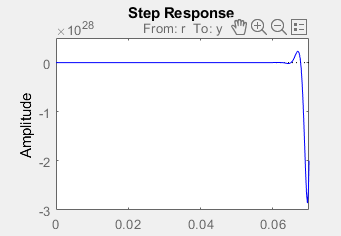

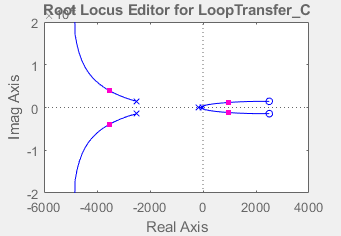


% SISO tool initialization
sisotool(sys, 100);

### REFERENCES:

- [https://dergipark.org.tr/tr/download/article-file/211352](https://dergipark.org.tr/tr/download/article-file/211352)

- [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9271817](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9271817)

- [https://iopscience.iop.org/article/10.1088/2631-8695/ad0760/pdf](https://iopscience.iop.org/article/10.1088/2631-8695/ad0760/pdf) (for time delays)